**C) MINIMIZATION OF TIME**

import casadi.*
opti = casadi.Opti();

T = opti.variable(); %time horizon
N = 100; % no of steps

dt = T/N;

X = opti.variable(4, N+1) %states over time

X = opti0_x_3


U = opti.variable(2, N) % control inputs over time

U = opti0_x_4


x0 = [-5; -4; 0; 0] %initial state

x0 =     -5
    -4
     0
     0


xf = [pi/2; 0; 0; 0] %final state

xf =     1.5708
         0
         0
         0


opti.minimize(T);
% parameters
b1 = 200.0;
b2 = 50.0;
b3 = 23.5;
b4 = 25.0;
b5 = 122.5;
c1 = -25.0;
g1 = 784.8;
g2 = 245.3;

%dynamics

f = @(X, U) [X(3);
    X(4);
    -(b5*U(1) - b3*U(2) - b5*g1*cos(X(1)) - b4*U(2)*cos(X(2)) + b3*g2*cos(X(1) + X(2)) - b5*g2*cos(X(1) + X(2)) + b4*g2*cos(X(1) + X(2))*cos(X(2)) + b3*c1*X(3)^2*sin(X(2)) + b5*c1*X(4)^2*sin(X(2)) + b4*c1*X(3)^2*cos(X(2))*sin(X(2)) + 2*b5*c1*X(3)*X(4)*sin(X(2)))/(b4^2*cos(X(2))^2 - b1*b5 + b3^2 - b2*b5*cos(X(2)) + 2*b3*b4*cos(X(2)));
    (b3*U(1) - b1*U(2) - b3*g1*cos(X(1)) - b2*U(2)*cos(X(2)) + b4*U(1)*cos(X(2)) + b1*g2*cos(X(1) + X(2)) - b3*g2*cos(X(1) + X(2)) + b2*g2*cos(X(1) + X(2))*cos(X(2)) - b4*g2*cos(X(1) + X(2))*cos(X(2)) - b4*g1*cos(X(1))*cos(X(2)) + b1*c1*X(3)^2*sin(X(2)) + b3*c1*X(4)^2*sin(X(2)) + b2*c1*X(3)^2*cos(X(2))*sin(X(2)) + b4*c1*X(4)^2*cos(X(2))*sin(X(2)) + 2*b3*c1*X(3)*X(4)*sin(X(2)) + 2*b4*c1*X(3)*X(4)*cos(X(2))*sin(X(2)))/(b4^2*cos(X(2))^2 - b1*b5 + b3^2 - b2*b5*cos(X(2)) + 2*b3*b4*cos(X(2)))]

f = function_handle with value:
    @(X,U)[X(3);X(4);-(b5*U(1)-b3*U(2)-b5*g1*cos(X(1))-b4*U(2)*cos(X(2))+b3*g2*cos(X(1)+X(2))-b5*g2*cos(X(1)+X(2))+b4*g2*cos(X(1)+X(2))*cos(X(2))+b3*c1*X(3)^2*sin(X(2))+b5*c1*X(4)^2*sin(X(2))+b4*c1*X(3)^2*cos(X(2))*sin(X(2))+2*b5*c1*X(3)*X(4)*sin(X(2)))/(b4^2*cos(X(2))^2-b1*b5+b3^2-b2*b5*cos(X(2))+2*b3*b4*cos(X(2)));(b3*U(1)-b1*U(2)-b3*g1*cos(X(1))-b2*U(2)*cos(X(2))+b4*U(1)*cos(X(2))+b1*g2*cos(X(1)+X(2))-b3*g2*cos(X(1)+X(2))+b2*g2*cos(X(1)+X(2))*cos(X(2))-b4*g2*cos(X(1)+X(2))*cos(X(2))-b4*g1*cos(X(1))*cos(X(2))+b1*c1*X(3)^2*sin(X(2))+b3*c1*X(4)^2*sin(X(2))+b2*c1*X(3)^2*cos(X(2))*sin(X(2))+b4*c1*X(4)^2*cos(X(2))*sin(X(2))+2*b3*c1*X(3)*X(4)*sin(X(2))+2*b4*c1*X(3)*X(4)*cos(X(2))*sin(X(2)))/(b4^2*cos(X(2))^2-b1*b5+b3^2-b2*b5*cos(X(2))+2*b3*b4*cos(X(2)))]



% constraints
Umin = -1000;
Umax = 1000;
Qdotmin = -3*pi/2;
Qdotmax = 3*pi/2;
opti.subject_to(Umin <= U <= Umax);
opti.subject_to(X(:,1)==x0);
opti.subject_to(X(:,end)==xf);
opti.subject_to(Qdotmin <= X(3,:)<= Qdotmax)
opti.subject_to(Qdotmin <= X(4,:)<= Qdotmax)
opti.subject_to(T >= 0);

for k =1:N
%     k1 = f(X(:, k), U(:, k));
%     k2 = f(X(:,k) + dt/2*k1, U(:,k));
%     k3 = f(X(:,k) + dt/2*k2, U(:,k));
%     k4 = f(X(:,k) + dt*k3, U(:,k));
%     x_next = X(:,k) + dt/6 * (k1+2*k2+2*k3+k4);
    x_next = X(:, k) + dt*f(X(:, k), U(:, k));
    opti.subject_to(X(:, k+1)==x_next);
%     opti.subject_to(Umin <= U <= Umax);
%     opti.subject_to(Qdotmin <= X(3,:)<= Qdotmax)
%     opti.subject_to(Qdotmin <= X(4,:)<= Qdotmax)
    opti.subject_to(T >= 0);
end
opti.set_initial(T, 1);


opti.solver('ipopt')
sol = opti.solve;


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit https://github.com/coin-or/Ipopt
******************************************************************************

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     2408
Number of nonzeros in inequality constraint Jacobian.:      503
Number of nonzeros in Lagrangian Hessian.............:     1600

Total number of variables............................:      605
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      408
Total number of inequality c

**Forward Kinematics**

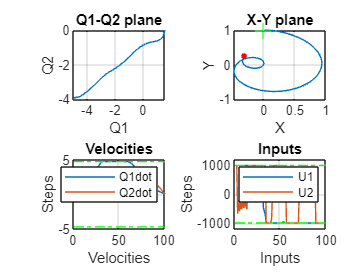

l1 = 0.5;
l2 = 0.5;
q1 = sol.value(X(1,:));
q2 = sol.value(X(2,:));
x = l1*cos(q1) + l2*cos(q1 + q2);
y = l1*sin(q1) + l2*sin(q1 + q2);

**Plots**

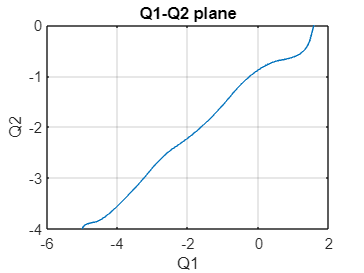

figure(1);
clf(1);
plot(q1', q2');
grid on;
hold on;
xlabel("Q1");
ylabel("Q2");
title('Q1-Q2 plane');

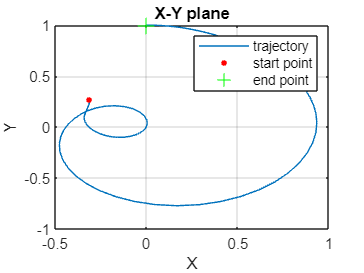


% Plot X-Y plane
figure(2);
clf(2);
plot(x', y');
grid on;
hold on;
xlabel("X");
ylabel("Y");
plot(x(1), y(1), 'r.', 'MarkerSize', 10);  % Start point
plot(x(end), y(end), 'g+', 'MarkerSize', 10);  % End point
legend('trajectory', 'start point', 'end point')
title('X-Y plane');

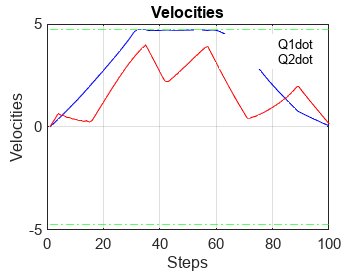


% Plot Velocities
figure(3);
clf(3);
plot(sol.value(X(3, :)'), 'b');
hold on;
plot(sol.value(X(4, :)'), 'r');
grid on;
plot(1:N+1, Qdotmin*ones(N+1,1), '-.g');
plot(1:N+1, Qdotmax*ones(N+1,1), '-.g');
xlabel("Steps");
ylabel("Velocities");
legend('Q1dot', 'Q2dot');
xlim([0 N]);
title('Velocities');

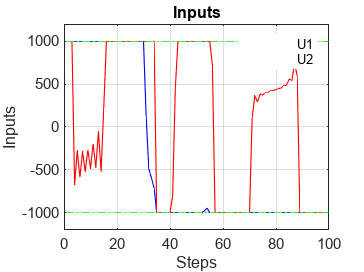


% Plot Inputs
figure(4);
clf(4);
plot(sol.value(U(1, :)'), 'b');
hold on;
plot(sol.value(U(2, :)'), 'r');
plot(1:N, Umin*ones(N,1), '-.g');
plot(1:N, Umax*ones(N,1), '-.g');
grid on;
xlabel("Steps");
ylabel("Inputs");
ylim([-1200 1200]);
xlim([0 N]);
legend('U1', 'U2');
title('Inputs');

**D) MINIMIZATION OF TIME AS A FIXED END TIME PROBLEM**

import casadi.*
opti = casadi.Opti();

T = 1;
N = 100; % no of steps


Tf = opti.variable(); % final time
dt = T/N;

X = opti.variable(4, N+1) %states over time

X = opti0_x_2


U = opti.variable(2, N) % control inputs over time

U = opti0_x_3


x0 = [-5; -4; 0; 0] %initial state

x0 =     -5
    -4
     0
     0


xf = [pi/2; 0; 0; 0] %final state

xf =     1.5708
         0
         0
         0


opti.minimize(Tf);
% parameters
b1 = 200.0;
b2 = 50.0;
b3 = 23.5;
b4 = 25.0;
b5 = 122.5;
c1 = -25.0;
g1 = 784.8;
g2 = 245.3;

%dynamics

f = @(X, U) [X(3);
    X(4);
    -(b5*U(1) - b3*U(2) - b5*g1*cos(X(1)) - b4*U(2)*cos(X(2)) + b3*g2*cos(X(1) + X(2)) - b5*g2*cos(X(1) + X(2)) + b4*g2*cos(X(1) + X(2))*cos(X(2)) + b3*c1*X(3)^2*sin(X(2)) + b5*c1*X(4)^2*sin(X(2)) + b4*c1*X(3)^2*cos(X(2))*sin(X(2)) + 2*b5*c1*X(3)*X(4)*sin(X(2)))/(b4^2*cos(X(2))^2 - b1*b5 + b3^2 - b2*b5*cos(X(2)) + 2*b3*b4*cos(X(2)));
    (b3*U(1) - b1*U(2) - b3*g1*cos(X(1)) - b2*U(2)*cos(X(2)) + b4*U(1)*cos(X(2)) + b1*g2*cos(X(1) + X(2)) - b3*g2*cos(X(1) + X(2)) + b2*g2*cos(X(1) + X(2))*cos(X(2)) - b4*g2*cos(X(1) + X(2))*cos(X(2)) - b4*g1*cos(X(1))*cos(X(2)) + b1*c1*X(3)^2*sin(X(2)) + b3*c1*X(4)^2*sin(X(2)) + b2*c1*X(3)^2*cos(X(2))*sin(X(2)) + b4*c1*X(4)^2*cos(X(2))*sin(X(2)) + 2*b3*c1*X(3)*X(4)*sin(X(2)) + 2*b4*c1*X(3)*X(4)*cos(X(2))*sin(X(2)))/(b4^2*cos(X(2))^2 - b1*b5 + b3^2 - b2*b5*cos(X(2)) + 2*b3*b4*cos(X(2)))]

f = function_handle with value:
    @(X,U)[X(3);X(4);-(b5*U(1)-b3*U(2)-b5*g1*cos(X(1))-b4*U(2)*cos(X(2))+b3*g2*cos(X(1)+X(2))-b5*g2*cos(X(1)+X(2))+b4*g2*cos(X(1)+X(2))*cos(X(2))+b3*c1*X(3)^2*sin(X(2))+b5*c1*X(4)^2*sin(X(2))+b4*c1*X(3)^2*cos(X(2))*sin(X(2))+2*b5*c1*X(3)*X(4)*sin(X(2)))/(b4^2*cos(X(2))^2-b1*b5+b3^2-b2*b5*cos(X(2))+2*b3*b4*cos(X(2)));(b3*U(1)-b1*U(2)-b3*g1*cos(X(1))-b2*U(2)*cos(X(2))+b4*U(1)*cos(X(2))+b1*g2*cos(X(1)+X(2))-b3*g2*cos(X(1)+X(2))+b2*g2*cos(X(1)+X(2))*cos(X(2))-b4*g2*cos(X(1)+X(2))*cos(X(2))-b4*g1*cos(X(1))*cos(X(2))+b1*c1*X(3)^2*sin(X(2))+b3*c1*X(4)^2*sin(X(2))+b2*c1*X(3)^2*cos(X(2))*sin(X(2))+b4*c1*X(4)^2*cos(X(2))*sin(X(2))+2*b3*c1*X(3)*X(4)*sin(X(2))+2*b4*c1*X(3)*X(4)*cos(X(2))*sin(X(2)))/(b4^2*cos(X(2))^2-b1*b5+b3^2-b2*b5*cos(X(2))+2*b3*b4*cos(X(2)))]



% constraints
Umin = -1000;
Umax = 1000;
Qdotmin = -3*pi/2;
Qdotmax = 3*pi/2;
opti.subject_to(Umin <= U <= Umax);
opti.subject_to(X(:,1)==x0);
opti.subject_to(X(:,end)==xf);
opti.subject_to(Qdotmin <= X(3,:)<= Qdotmax)
opti.subject_to(Qdotmin <= X(4,:)<= Qdotmax)
opti.subject_to(Tf >= 0);

for k =1:N
%     k1 = f(X(:, k), U(:, k));
%     k2 = f(X(:,k) + dt/2*k1, U(:,k));
%     k3 = f(X(:,k) + dt/2*k2, U(:,k));
%     k4 = f(X(:,k) + dt*k3, U(:,k));
%     x_next = X(:,k) + dt/6 * (k1+2*k2+2*k3+k4);
    x_next = X(:, k) + dt*Tf*f(X(:, k), U(:, k));
    opti.subject_to(X(:, k+1)==x_next);
%     opti.subject_to(Umin <= U <= Umax);
%     opti.subject_to(Qdotmin <= X(3,:)<= Qdotmax)
%     opti.subject_to(Qdotmin <= X(4,:)<= Qdotmax)
%     opti.subject_to(Tf >= 0);
end
opti.set_initial(Tf, 1);


opti.solver('ipopt')
sol = opti.solve;


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit https://github.com/coin-or/Ipopt
******************************************************************************

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:     2408
Number of nonzeros in inequality constraint Jacobian.:      403
Number of nonzeros in Lagrangian Hessian.............:     1600

Total number of variables............................:      605
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:      408
Total number of inequality c

**Forward Kinematics**

l1 = 0.5;
l2 = 0.5;
q1 = sol.value(X(1,:));
q2 = sol.value(X(2,:));
x = l1*cos(q1) + l2*cos(q1 + q2);
y = l1*sin(q1) + l2*sin(q1 + q2);

**Plots**

figure(1)
clf(1);
subplot(2, 2, 1);
plot(q1', q2')
grid on;
hold on;
xlabel("Q1");
ylabel("Q2");
title('Q1-Q2 plane')

subplot(2, 2, 2);
plot(x', y')
grid on;
hold on;
xlabel("X");
ylabel("Y");
plot(x(1), y(1), 'r.', 'MarkerSize', 10);  % Start point
plot(x(end), y(end), 'g+', 'MarkerSize', 10);  % End point
title('X-Y plane')

subplot(2, 2, 3);
plot(sol.value(X([3 4], :)'))
grid on;
hold on;
xlabel("Velocities");
ylabel("Steps");
plot(1:N+1, Qdotmin*ones(N+1,1), '-.g');
plot(1:N+1, Qdotmax*ones(N+1,1), '-.g');
legend('Q1dot', 'Q2dot')
title('Velocities')

subplot(2, 2, 4);
plot(sol.value(U([1 2], :)'))
grid on;
hold on;
xlabel("Inputs");
ylabel("Steps");
plot(1:N, Umin*ones(N,1), '-.g');
plot(1:N, Umax*ones(N,1), '-.g');
ylim([-1200 1200]);
legend('U1', 'U2')
title('Inputs')